parameters

n = 1001;
t_max = 60;
t = linspace(0, t_max,n);
x_or = 2.5*sin(t.*(pi/15))+.5;
y_or = 7*cos(t.*(pi/30))-7.5;
ang = atan2(y_or, x_or);
x = x_or + l.*cos(ang);
y = y_or + l.*sin(ang);
dx = [diff(x)./diff(t(1:2))];
dy = [diff(y)./diff(t(1:2))];
dx = [dx,dx(end)];
dy = [dy,dy(end)];
ddx = [diff(dx(2:end))./diff(t(1:2))];
ddy = [diff(dy(2:end))./diff(t(1:2))];
ddx = [ddx,ddx(end),ddx(end)];
ddy = [ddy,ddy(end),ddy(end)];
% for i = 1:n
%     if i < n/3
%         y(i) = sin(t(i));
%     elseif i < 2*n/3
%         y(i) = -t(i)*.05+1;
%     else
%         y(i) = cos(t(i))+t(i)*.05-2;
%     end
% end

tf = t(length(t));
ts = tf./(n-1);

lambda_x = 20;
lambda_y = 2;
lambda = [lambda_x; lambda_y];
k = 1;
omega_bar_x = 0.5;
omega_bar_sqrt_x = sqrt(omega_bar_x);
omega_bar_y = 0.5;
omega_bar_sqrt_y = sqrt(omega_bar_y);
omega_bar_sqrt = [omega_bar_sqrt_x; omega_bar_sqrt_y];
gamma_x = 1;
gamma_sqrt_x = sqrt(gamma_x);
gamma_y = .5;
gamma_sqrt_y = sqrt(gamma_y);
gamma_sqrt = [gamma_sqrt_x ; gamma_sqrt_y];

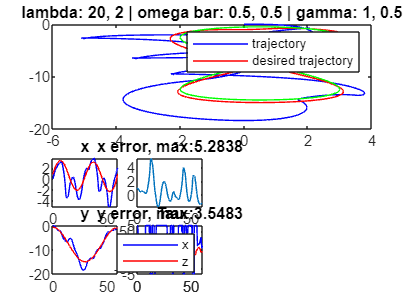

sim('control');
x_model = squeeze(out.simout.Data(1,1,:));
y_model = squeeze(out.simout.Data(2,1,:));
tau = [out.simout1.Data(:,1),out.simout1.Data(:,3)];

subplot(2,1,1)
plot(x_model, y_model,'b', x,y,'r',x_or,y_or,'g');
legend('trajectory', 'desired trajectory');
title(['lambda: ',num2str(lambda_x),', ',num2str(lambda_y),' | omega bar: '...
    ,num2str(omega_bar_x),', ',num2str(omega_bar_y), ' | gamma: '...
    ,num2str(gamma_x),', ',num2str(gamma_y)]);
subplot(4,4,9)
plot(t, x_model, 'b', t, x, 'r'), title('x');
%legend('x', 'desired x');
subplot(4,4,13)
plot(t, y_model, 'b', t, y, 'r'), title('y');
%legend('y', 'desired y');
subplot(4,4,10)
plot(t, x'-x_model), title(['x error, max:',num2str(max(x'-x_model))]);
subplot(4,4,14)
plot(t, y'-y_model), title(['y error, max:',num2str(max(y'-y_model))]);
subplot(2,2,4)
plot(t, tau(:,1), 'b', t, tau(:,2), 'r'), title('Tau'), legend('x', 'z');